clc
tic

t   = out.tout;
Uabc = out.ScopeData.signals(1).values;
Iabc = out.ScopeData.signals(2).values;
ud   = out.ScopeData1.signals(1).values;
id   = out.ScopeData1.signals(2).values;

tmin = t(1);
tmax = t(end);

%% ===================== 2) 风格1：全局绘图风格 =====================
set(groot, 'defaultFigureColor', 'w');

set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');

set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultAxesLineWidth', 1.1);
set(groot, 'defaultLineLineWidth', 1.6);
set(groot, 'defaultAxesBox', 'on');
set(groot, 'defaultAxesTickDir', 'out');

set(groot, 'defaultAxesTickLabelInterpreter', 'tex');
set(groot, 'defaultTextInterpreter', 'tex');
set(groot, 'defaultLegendInterpreter', 'tex');

% Colors
C1 = [0.00, 0.45, 0.74];   % blue
C2 = [0.85, 0.33, 0.10];   % orange
C3 = [0.47, 0.67, 0.19];   % green
C4 = [0.49, 0.18, 0.56];   % purple

%% ===================== 3) 直流侧 id：重采样 + 纹波频谱/指标 =====================
fs_line = 50;              % 电网频率(Hz)
fr = 6*fs_line;            % 6脉波纹波基频 = 300 Hz

% -------- 3.1 检查是否等间隔采样，并重采样为均匀时间轴 --------
t = t(:);
id = id(:);

dt = diff(t);
Fs_est = 1/mean(dt);

% 判定 variable-step：dt 波动超过阈值则重采样
% 阈值可调：建议用相对波动判定更鲁棒
rel_jitter = (max(dt) - min(dt)) / max(mean(dt), eps);

if rel_jitter > 1e-3
    % 用估计的平均采样频率构造均匀时间轴
    Fs = Fs_est;
    t_u = (t(1):1/Fs:t(end)).';
    id_u = interp1(t, id, t_u, 'linear', 'extrap');
else
    Fs = Fs_est;
    t_u = t;
    id_u = id;
end

% -------- 3.2 取稳态段：末尾整周期截取--------
Ncycle = 20;                         % 取末尾 20 个 50Hz 周期（可调）
Tseg = Ncycle / fs_line;
t_end = t_u(end);
t_start = t_end - Tseg;

seg = (t_u >= t_start);
x = id_u(seg);
x = x(:);

% 保证偶数长度
L = length(x);
L = L - mod(L,2);
x = x(1:L);

% -------- 3.3 直流分量与纹波指标 --------
Idc = mean(x);
xr  = x - Idc;                        % 纹波分量

Ir_rms = rms(xr);
ripple_factor_percent = Ir_rms / max(abs(Idc), eps) * 100;

% -------- 3.4 对纹波 xr 做 FFT（单边峰值幅值谱）--------
w  = hann(L);
xw = xr .* w;

Y  = fft(xw);
P2 = abs(Y)/L;

P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;

% Hann 窗 coherent gain 修正
P1 = P1 / mean(w);                    % 单边"峰值幅值"(peak)

% -------- 3.5 以 300Hz 为基波计算 ripple-THD（更符合6脉波纹波）--------
Hmax = floor((Fs/2)/fr);
Ah   = zeros(Hmax,1);
idxH = zeros(Hmax,1);

for k = 1:Hmax
    [~, idxH(k)] = min(abs(f - k*fr));
    Ah(k) = P1(idxH(k));              % peak
end

A1 = Ah(1);
THD_ripple_percent = sqrt(sum(Ah(2:end).^2)) / max(A1, eps) * 100;

fprintf('====================================\n');

fprintf('variable-step重采样判定: rel_jitter = %.3g\n', rel_jitter);

variable-step重采样判定: rel_jitter = 2.11


fprintf('等效采样频率 Fs = %.3f Hz\n', Fs);

等效采样频率 Fs = 21143.333 Hz


fprintf('Idc = %.6g A\n', Idc);

Idc = 100.748 A


fprintf('Ir_rms = %.6g A, ripple factor = %.4f %%\n', Ir_rms, ripple_factor_percent);

Ir_rms = 11.3053 A, ripple factor = 11.2214 %


fprintf('ripple-THD (基波=300Hz) = %.4f %%\n', THD_ripple_percent);

ripple-THD (基波=300Hz) = 19.6523 %


fprintf('====================================\n');

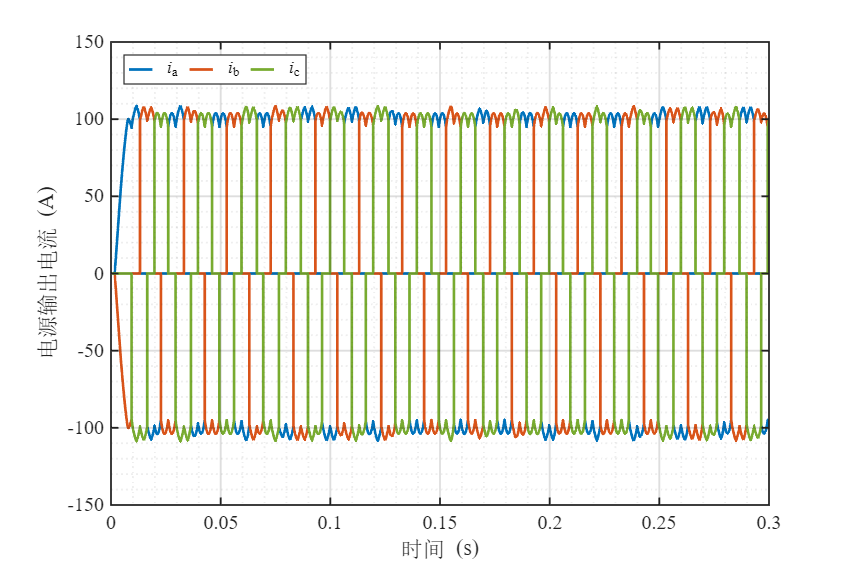


% -------- 3.6 频谱柱状图数据：按 300Hz 倍频画 --------
Kplot = min(Hmax, 30);                % 只画前 30 个纹波谐波（可调）
ff   = (0:Kplot) * fr;                % 0,300,600,...
Abar = [0; Ah(1:Kplot)];              % DC这里显示0（因为FFT的是纹波）

%% ===================== 4) 风格1：分开绘制 4 个独立图 =====================

% ---- (1) Iabc ----
fig1 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax1 = axes(fig1); %#ok<LAXES>
plot(t, Iabc(:,1), 'Color', C1); hold on;
plot(t, Iabc(:,2), 'Color', C2);
plot(t, Iabc(:,3), 'Color', C3);
grid on; grid minor;
xlim([tmin, tmax]);
xlabel('\fontname{SimSun}时间\fontname{Times New Roman} (s)');
ylabel('\fontname{SimSun}电源输出电流\fontname{Times New Roman} (A)');

leg1 = legend({'{\it i}_a','{\it i}_b','{\it i}_c'}, ...
    'Location','northwest','NumColumns',3);
set(leg1, 'FontName','Times New Roman', 'FontSize', 11, ...
    'Box','on', 'EdgeColor',[0.2 0.2 0.2], 'LineWidth', 0.8, ...
    'Color','white', 'TextColor','black', 'ItemTokenSize',[14 10]);

ax1.GridAlpha = 0.15; ax1.MinorGridAlpha = 0.08;
set(ax1, 'Layer', 'top');

% ---- (2) ud ----
fig2 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax2 = axes(fig2); %#ok<LAXES>
plot(t, ud, 'Color', C1);
grid on; grid minor;
xlim([tmin, tmax]);
xlabel('\fontname{SimSun}时间\fontname{Times New Roman} (s)');
ylabel('\fontname{SimSun}总输出电压\fontname{Times New Roman} (V)');
ax2.GridAlpha = 0.15; ax2.MinorGridAlpha = 0.08;
set(ax2, 'Layer', 'top');

% ---- (3) id ----
fig3 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax3 = axes(fig3); %#ok<LAXES>
plot(t, id, 'Color', C4);
grid on; grid minor;
xlim([tmin, tmax]);
xlabel('\fontname{SimSun}时间\fontname{Times New Roman} (s)');
ylabel('\fontname{SimSun}总输出电流\fontname{Times New Roman} (A)');
ax3.GridAlpha = 0.15; ax3.MinorGridAlpha = 0.08;
set(ax3, 'Layer', 'top');

% ---- (4) 频谱柱状图：直流侧电流纹波(基频=300Hz) ----
fig4 = figure('Units','centimeters','Position',[3 3 18 12], 'Color','w');
ax4 = axes(fig4); %#ok<LAXES>
bar(ff, Abar, "LineWidth", 1.2, "FaceColor", C3);
grid on; grid minor;
xlim([min(ff), max(ff)]);
ylim([0, max(Abar)*1.10]);

xlabel('\fontname{SimSun}频率\fontname{Times New Roman} (Hz)');
ylabel('\fontname{SimSun}纹波谐波幅值(peak)\fontname{Times New Roman} (A)');
title(sprintf('\\fontname{SimSun}直流侧电流纹波频谱(基频=300Hz)  r=%.3f%%%%, THD=%.3f%%%%\\fontname{Times New Roman}', ...
    ripple_factor_percent, THD_ripple_percent));

ax4.GridAlpha = 0.15; ax4.MinorGridAlpha = 0.08;
set(ax4, 'Layer', 'top');

%% ===================== 5) 导出（四张图分别导出） =====================
print(fig1, 'filterPI结果_Iabc_风格1',  '-dpng', '-r600');

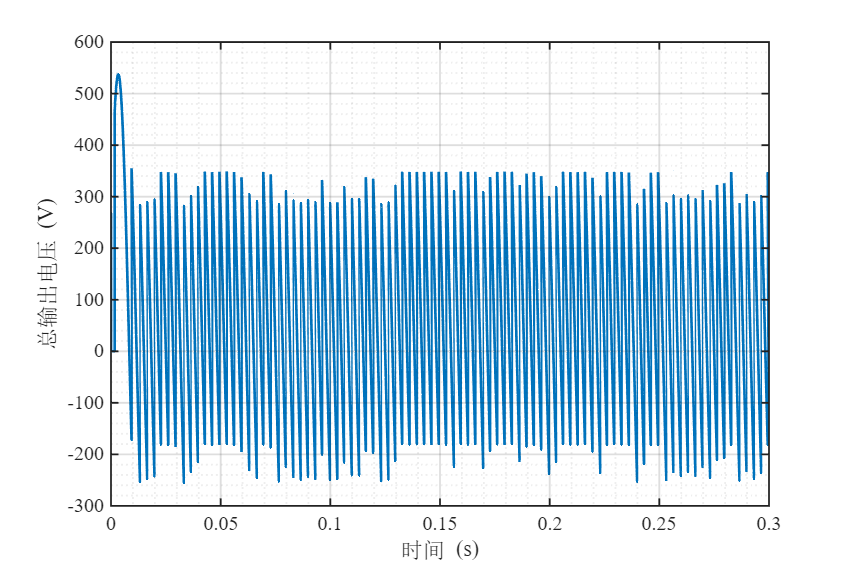

print(fig2, 'filterPI结果_ud_风格1',    '-dpng', '-r600');

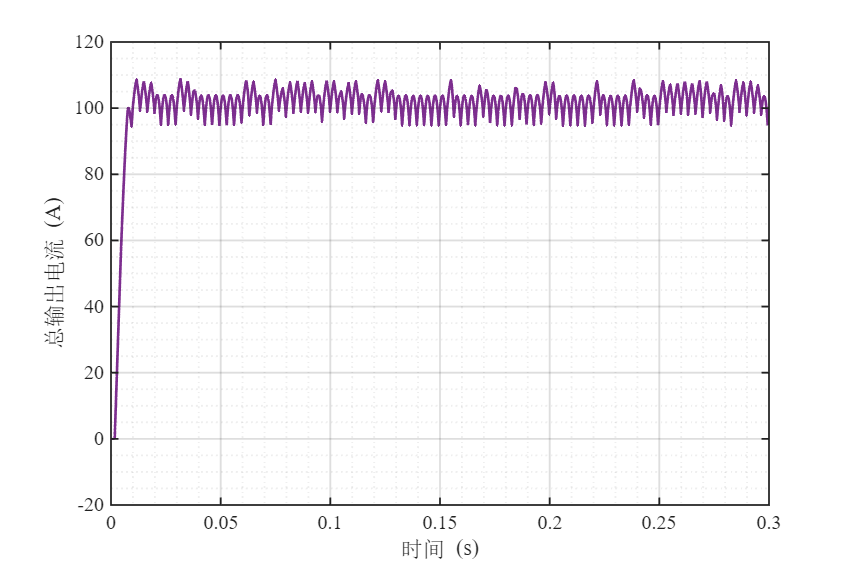

print(fig3, 'filterPI结果_id_风格1',    '-dpng', '-r600');

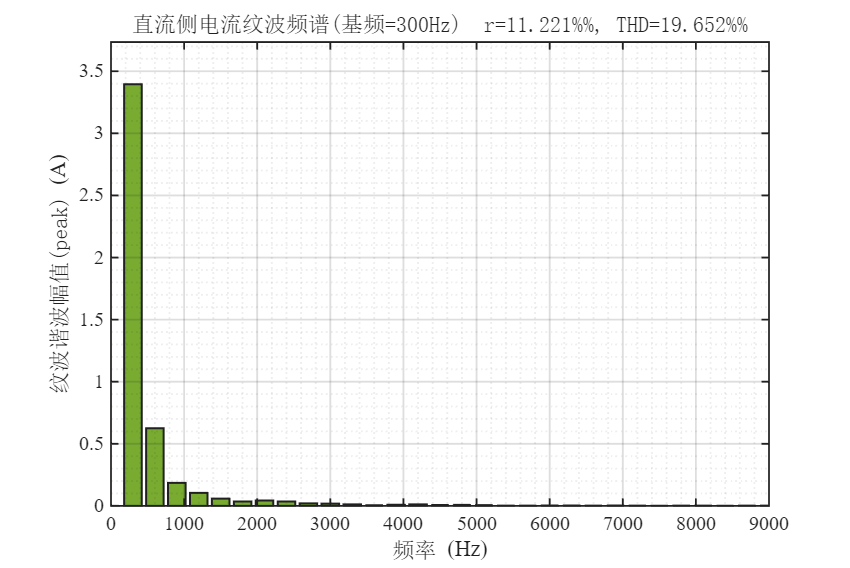

print(fig4, 'filterPI结果_纹波频谱_风格1',  '-dpng', '-r600');


toc

历时 11.735518 秒。
